## Leer información de la tabla

dh = readtable('datos\tabla_DH\robot9.csv');

% Convertir las columnas numéricas a double
thetaNum = deg2rad(double(dh.theta));
dNum     = double(dh.d);
aNum     = double(dh.a);
alphaNum = deg2rad(double(dh.alpha));
min = double(dh.min);
max = double(dh.max);

% Convertir la columna de tipo a char (se asume 'r' para revoluta y 'p' para prismática)
tipo = char(dh.tipo);

n = size(dh,1);  % Número de eslabones/juntas

## Crear variables simbólicas según el tipo de articulación

jointSymbols = sym(zeros(n,1));  % Preasignar vector simbólico
for i = 1:n
    if tipo(i) == 'r'
        % Junta revoluta: el ángulo es variable
        jointSymbols(i) = sym(sprintf('theta_%d', i));
    elseif tipo(i) == 'p'
        % Junta prismática: el desplazamiento es variable
        jointSymbols(i) = sym(sprintf('d_%d', i));
    else
        error('Tipo de articulación no reconocido en la fila %d.', i);
    end
end

## Construir las matrices de transformación homogénea simbólicas para cada eslabón

## 
$$A_i=R_{z,\theta_i}T_{z,d_i}T_{x,a_i}R_{x,\alpha_i}$$


% Se convierten los parámetros numéricos a simbólicos usando sym()
A = sym(zeros(4,4,n));  % Preasignar matriz simbólica para cada transformación
offset = zeros(n,1);
for i = 1:n
    % Para cada articulación, dependiendo del tipo se asigna la variable simbólica
    if tipo(i) == 'r'
        % Junta revoluta: θ es variable, d es fija
        theta_sym = jointSymbols(i);
        offset(i) = thetaNum(i); % Guarda el valor de la variable como offset
        d_sym = sym(dNum(i));
    elseif tipo(i) == 'p'
        % Junta prismática: d es variable, θ es fija
        theta_sym = sym(thetaNum(i));
        d_sym = jointSymbols(i);
        offset(i) = dNum(i); % Guarda el valor de la variable como offset
    end
    a_sym     = sym(aNum(i));
    alpha_sym = sym(alphaNum(i));
    
    % Calcular la transformación homogénea para el eslabón i
    % Se asume que las funciones HRz, HTz, HTx y HRx están definidas y aceptan argumentos simbólicos
    A(:,:,i) = simplify(HRz(theta_sym) * HTz(d_sym) * HTx(a_sym) * HRx(alpha_sym));
end

## Calcular la transformación homogénea acumulada (de la base al extremo)

## 
$$T_0^n =A_0 A_1 \ldotp \ldotp \ldotp A_n$$


T = sym(zeros(4,4,n));
T(:,:,1) = A(:,:,1);
for i = 2:n
    T(:,:,i) = simplify(T(:,:,i-1) * A(:,:,i));
end

## Graficar Robot

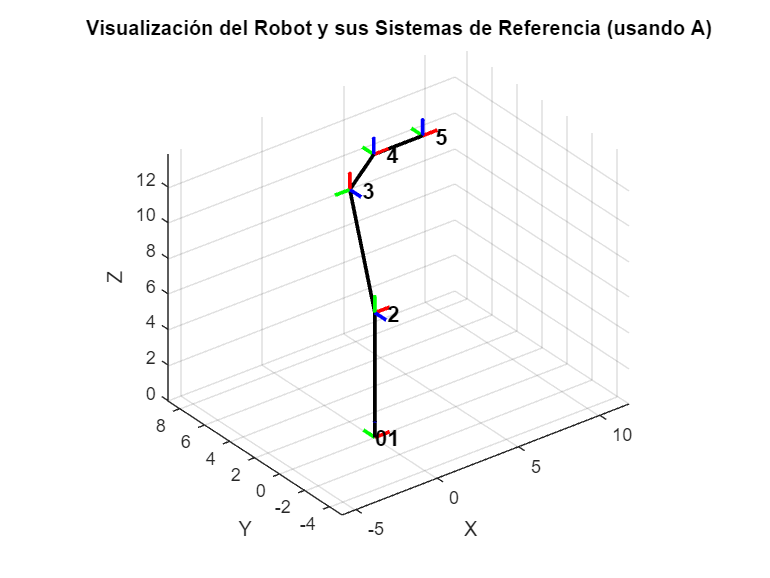

plotRobot(A, offset, tipo, 1);